# Stubbornness in the Friedkin-Johnsen model: a short demonstration

projectDir = fileparts(mfilename('fullpath'));
while ~isfile(fullfile(projectDir, 'setup_paths.m')) && ...
        ~strcmp(projectDir, fileparts(projectDir))
    projectDir = fileparts(projectDir);
end
addpath(projectDir);
setup_paths;

## 1. The two models

French-DeGroot, pure averaging:     x(k+1) = W x(k).

Friedkin-Johnsen, averaging plus an anchor:     x(k+1) = Lambda W x(k) + (I - Lambda) u.

Agent by agent, the FJ update reads   x_i(k+1) = lambda_i * sum_j w_ij x_j(k) + (1 - lambda_i) u_i.

- W - the row-stochastic matrix of social influence. W(i,j) > 0 means agent i accords weight to agent j, so row i lists whom i listens to.

- Lambda = diag(lambda_1, ..., lambda_n) - each agents susceptibility, i.e. how open it is to social influence.

- u - the prejudices: a pre-existing opinion, formed outside the discussion, that does not change while the discussion runs.

- 1 - lambda_i - the weight of the anchoring term: how tightly agent i is held to its own prejudice at EVERY step, not just at the start.

The whole difference is that second term. Two limiting cases make it concrete: with lambda_i = 1 for every agent the anchor disappears and FJ IS French-DeGroot; with lambda_i = 0 agent i never moves off u_i at all. Friedkin-Johnsen is the one-parameter family in between, and the four experiments below are about what lives in that interval.

Reference throughout: Proskurnikov & Tempo, Part I, section 6. Opinions are scalar.

## 2. The network used in Experiments 1-3

Five agents in a line, each listening to itself and to its immediate neighbours. It is small enough to read off the picture, and it satisfies the assumptions the theory needs: W is row-stochastic, and the graph is strongly connected and aperiodic. Those two properties matter later - strong connectivity is what makes Corollary 4.1 apply in Experiment 3, and aperiodicity is what makes the DeGroot baseline in Experiment 1 actually converge, so the comparison is a fair one rather than one FJ wins by default.

WHY THIS NETWORK. The graph is an instrument, not scenery: each experiment below isolates one variable, so the network has to be chosen to make everything else inert. Five properties are doing work.

- It is APERIODIC and ROOTED, so French-DeGroot genuinely converges. This is the most important choice in the notebook. On a directed cycle - the topology used in Chapter 4 - DeGroot never settles at all, and Experiment 1 would then be demonstrating periodicity rather than stubbornness. Because DeGroot converges perfectly well here, the only thing left to explain the difference in Experiment 1 is the anchor term.

- It is STRONGLY CONNECTED, so by Corollary 4.1 every configuration in Experiment 3 is asymptotically stable no matter which agents are anchored. Without this, moving the anchor from one agent to another could silently change whether the model is stable at all, and Experiment 3 would be varying two things at once instead of one.

- W is ROW-STOCHASTIC, so rho(W) = 1 and therefore rho(lambda W) = lambda exactly for a uniform Lambda. The parameter being turned in Experiment 2 IS the stability margin, which is why that experiment needs one number rather than a spectral plot.

- The geometry is ONE-DIMENSIONAL, so in Experiment 3 two opposing prejudices produce a readable gradient: distance to each anchor is a single number, and V comes out as a clean interpolation along the line. On a star or a complete graph the same experiment gives numbers that are correct but carry no visible structure.

- Social power is NOT UNIFORM, p = [2 3 3 3 2]/13, so the DeGroot consensus is a genuine weighted average rather than the plain arithmetic mean that a ring or a complete graph would have given - which would invite the wrong mental model of what averaging does.

Two tempting alternatives were rejected for concrete reasons. The directed cycle makes Experiment 1 trivial, as above. The measured Friedkin-Johnsen 1999 matrix of Part I, equation (24), is attractive because it is real data, but its agent 3 has w_33 = 1 and is therefore already stubborn INSIDE W itself; DeGroot on that network converges to agent 3s opinion rather than to a weighted average, so the baseline of Experiment 1 would be muddied by a stubbornness hiding in the wrong matrix. It belongs in a later chapter, where the real data is the point.

n = 5;
A = [1 1 0 0 0        % 1 listens to itself and 2
     1 1 1 0 0        % 2 listens to 1, itself, 3
     0 1 1 1 0        % 3 listens to 2, itself, 4
     0 0 1 1 1        % 4 listens to 3, itself, 5
     0 0 0 1 1];      % 5 listens to 4 and itself
W = row_stochastic(A);

g = graph_summary(W);
fprintf('row-stochastic %d | strongly connected %d | period %d | DeGroot reaches consensus %d\n', ...
    is_row_stochastic(W), numel(g.components) == 1, graph_period(W), g.consensus);

row-stochastic 1 | strongly connected 1 | period 1 | DeGroot reaches consensus 1


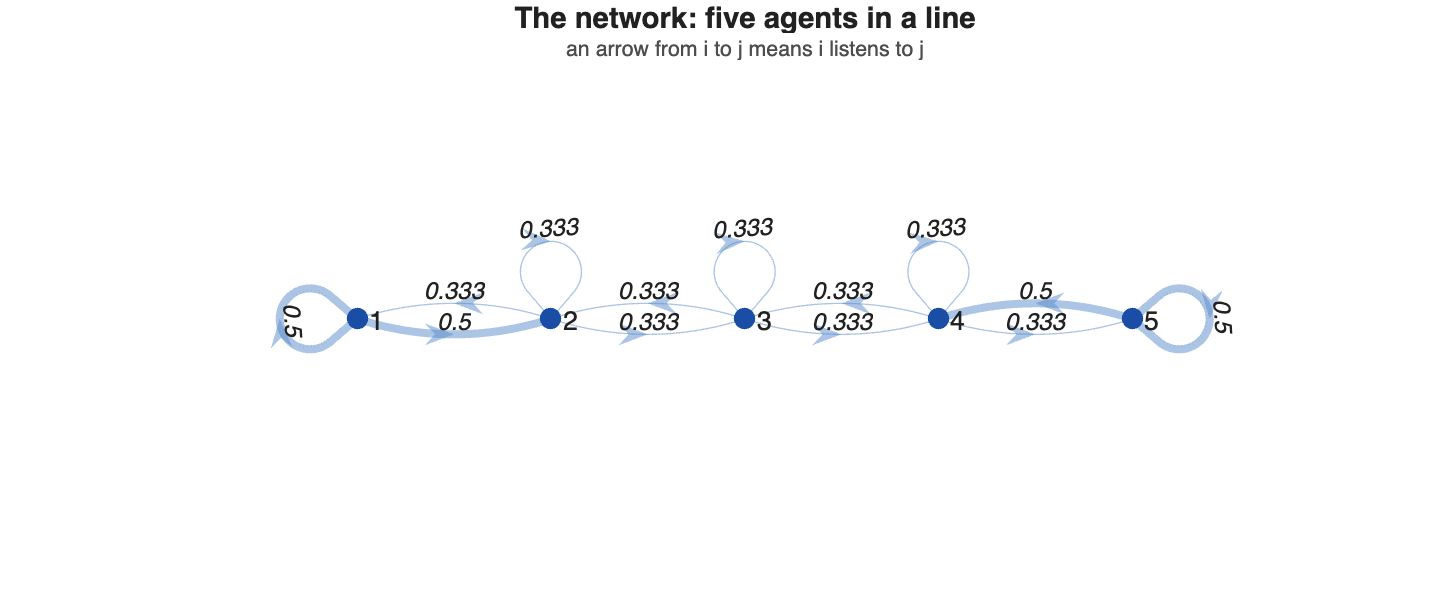


figure('Position',[0 0 720 300]);
plot_graph(W, [], 'Layout', [(1:5).' zeros(5,1)], ...
    'Title','The network: five agents in a line', ...
    'Subtitle','an arrow from i to j means i listens to j')

## 3. Experiment 1 - what the prejudice term changes

QUESTION. Same network, same initial opinions: what does adding the anchor term do to the outcome?

SETUP. The two models are run side by side on the same W and the same x(0). The prejudices are set to the initial opinions, u = x(0) - the classical Friedkin-Johnsen assumption. (Part I deliberately allows u and x(0) to be independent; taking them equal here isolates the anchor term as the only difference between the two runs.) Susceptibility is uniform, lambda_i = 0.8, so no agent is frozen - every agent is genuinely listening, and gives its own prejudice only 20% of the weight.

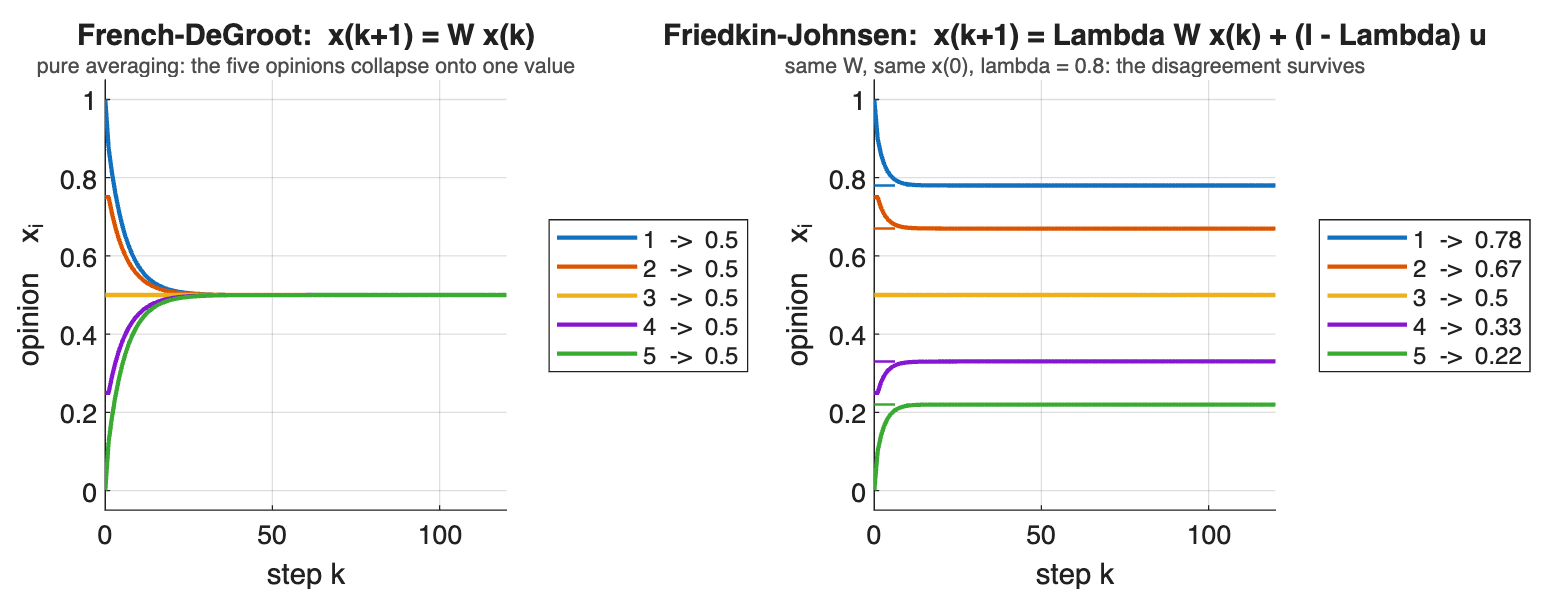

x0  = [1; 0.75; 0.5; 0.25; 0];     % opinions spread across the line, on a 0-1 scale
u   = x0;                          % prejudices = initial opinions
lam = 0.8 * ones(n,1);             % everybody 80% open to social influence

Xd = sim_degroot(W, x0, 120);
Xf = sim_friedkin_johnsen(W, lam, u, x0, 120);

figure('Position',[0 0 1150 440]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
nexttile;
plot_opinions(Xd, [], 'Title','French-DeGroot:  x(k+1) = W x(k)', ...
    'Subtitle','pure averaging: the five opinions collapse onto one value');
ylim([-0.05 1.05]);
nexttile;
plot_opinions(Xf, [], 'Limit', fj_equilibrium(W, lam, u), ...
    'Title','Friedkin-Johnsen:  x(k+1) = Lambda W x(k) + (I - Lambda) u', ...
    'Subtitle','same W, same x(0), lambda = 0.8: the disagreement survives');
ylim([-0.05 1.05]);


fprintf('DeGroot  x(inf) = %s   spread %.4f\n', ...
    mat2str(round(Xd(:,end).',4)), max(Xd(:,end))-min(Xd(:,end)));

DeGroot  x(inf) = [0.5 0.5 0.5 0.5 0.5]   spread 0.0000


fprintf('FJ       x(inf) = %s   spread %.4f\n', ...
    mat2str(round(Xf(:,end).',4)), max(Xf(:,end))-min(Xf(:,end)));

FJ       x(inf) = [0.78 0.67 0.5 0.33 0.22]   spread 0.5600


INTERPRETATION. In DeGroot every update is a convex combination of the current opinions, so the spread can only shrink; on a strongly connected, aperiodic graph it shrinks to zero and the group agrees - here on exactly 0.5, the social-power-weighted average of x(0). Nothing in the model can stop that.

In FJ each agent re-injects its own prejudice at every step, so the averaging is fighting a constant pull that never decays. The group still converges - the trajectories are flat after about twenty steps - but it converges to five DIFFERENT values, 0.78 / 0.67 / 0.50 / 0.33 / 0.22, spread 0.56. This is the central point: the disagreement is not a failure to converge, and it is not caused by a broken network. The network is fully connected, every agent keeps listening to its neighbours forever, and they still end up disagreeing. Classical averaging cannot produce this at all.

Note also the ORDER of the final opinions: it is the same as the order of the prejudices. Agent 1 ends highest, agent 5 lowest. The group has moved towards each other without merging.

## 4. Experiment 2 - what the susceptibility parameter does

QUESTION. The network and the prejudices are now fixed. What does turning the single knob lambda do?

SETUP. Same W, same u = x(0) as above, and Lambda = lambda I so that one number describes the whole group. Four representative values are shown rather than a sweep: lambda = 0, 0.5, 0.9 and 1. The two ends are the two models we already know.

sel = [0 0.5 0.9 1];

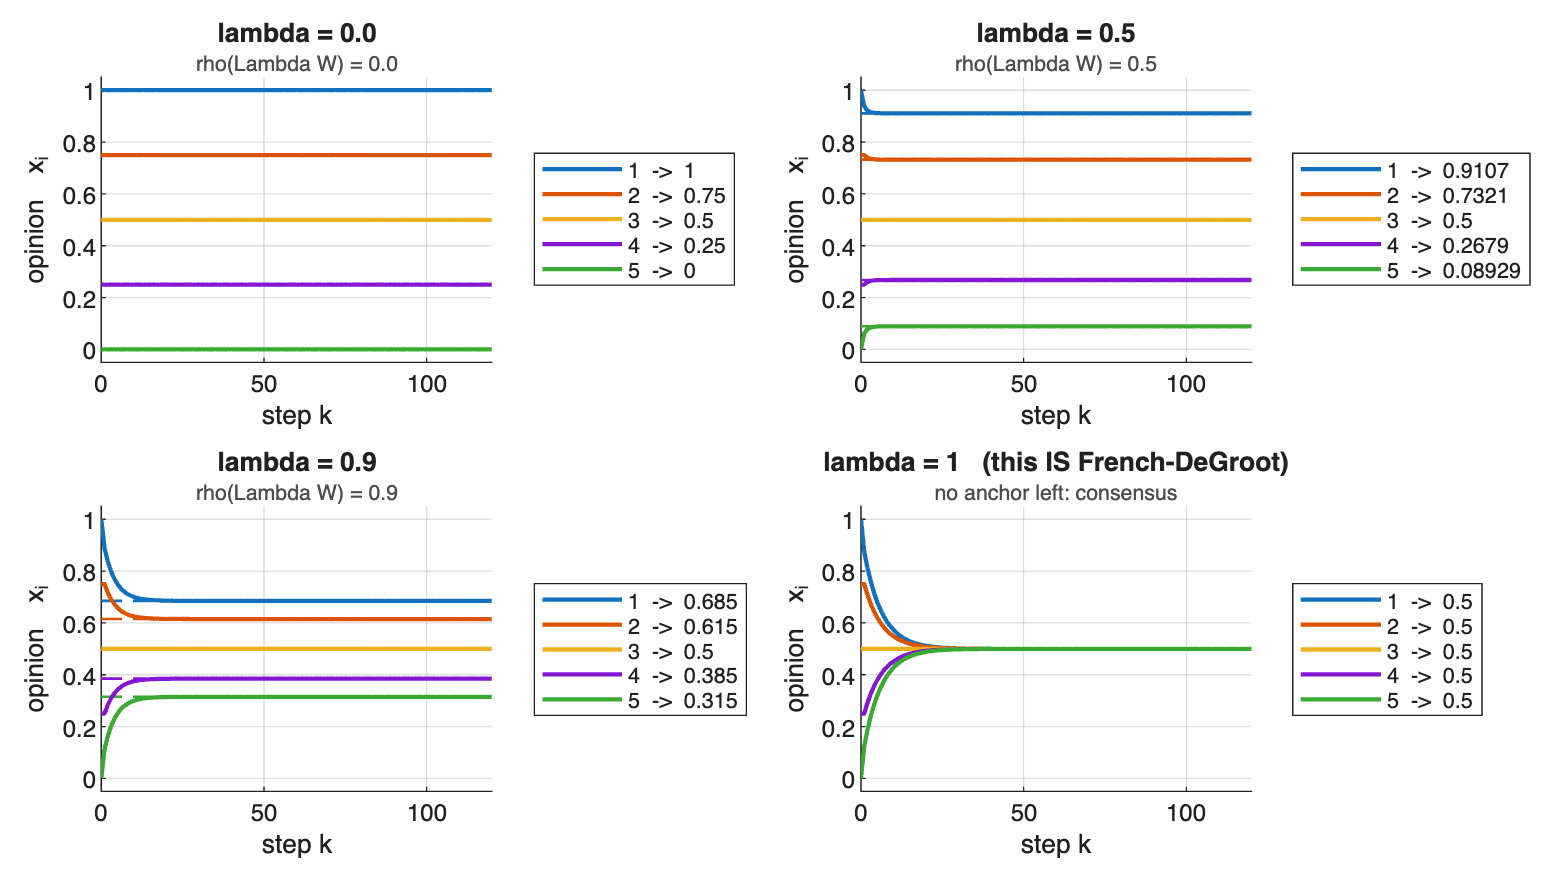


figure('Position',[0 0 1150 640]);
tiledlayout(2, 2, 'TileSpacing','compact', 'Padding','compact');
for l = sel
    if l == 1
        X = sim_degroot(W, x0, 120);
        nexttile; plot_opinions(X, [], 'Title','lambda = 1   (this IS French-DeGroot)', ...
            'Subtitle','no anchor left: consensus');
    else
        X = sim_friedkin_johnsen(W, l*ones(n,1), u, x0, 120);
        nexttile; plot_opinions(X, [], 'Limit', fj_equilibrium(W, l*ones(n,1), u), ...
            'Title', sprintf('lambda = %.1f', l), ...
            'Subtitle', sprintf('rho(Lambda W) = %.1f', l));
    end
    ylim([-0.05 1.05]);
end


fprintf(' lambda   rho(Lambda W)   spread of x(inf)\n');

 lambda   rho(Lambda W)   spread of x(inf)


for l = sel
    if l == 1
        Xl = sim_degroot(W, x0, 400);  s = max(Xl(:,end)) - min(Xl(:,end));
    else
        xi = fj_equilibrium(W, l*ones(n,1), u);  s = max(xi) - min(xi);
    end
    fprintf('  %.1f       %.4f          %.4f\n', l, max(abs(eig(l*W))), s);
end

  0.0       0.0000          1.0000
  0.5       0.5000          0.8214
  0.9       0.9000          0.3700
  1.0       1.0000          0.0000


INTERPRETATION. The four panels interpolate between the two things we already understand. At lambda = 0 nobody listens at all and every agent sits on its prejudice for ever, spread 1.00. At lambda = 1 the anchor is gone, the model is exactly DeGroot, and the spread is 0. In between, raising lambda gives the averaging more weight and the prejudices less, and the final spread falls monotonically: 1.00, 0.82, 0.37, 0.

The spectral radius says the rest. Because W is row-stochastic its spectral radius is 1, so for a uniform Lambda we get rho(Lambda W) = lambda exactly. That single number is what decides convergence: it is strictly below 1 for every lambda < 1, which is why FJ settles at all and does so at rate lambda, and it hits 1 precisely at lambda = 1, where the eigenvalue 1 of W comes back and with it the consensus mode. So there is a genuine trade-off rather than a free lunch: more susceptibility buys more agreement and pays for it with slower convergence, and at lambda = 1 the agreement is total and the asymptotic stability is gone.

## 5. Experiment 3 - one prejudiced agent, or several?

QUESTION. In Experiment 1 every agent was prejudiced. How much of the effect survives if only one or two agents are anchored?

SETUP. Same network. Now only the named agents have lambda_i = 0.5; everybody else has lambda_i = 1, i.e. pure DeGroot behaviour. Three cases, differing only in who is anchored and to what. Because the graph is strongly connected and Lambda is not the identity, Corollary 4.1 applies in all three: every agent is P-dependent, so the model is asymptotically stable and x(inf) = V u with V = (I - Lambda W)^-1 (I - Lambda).

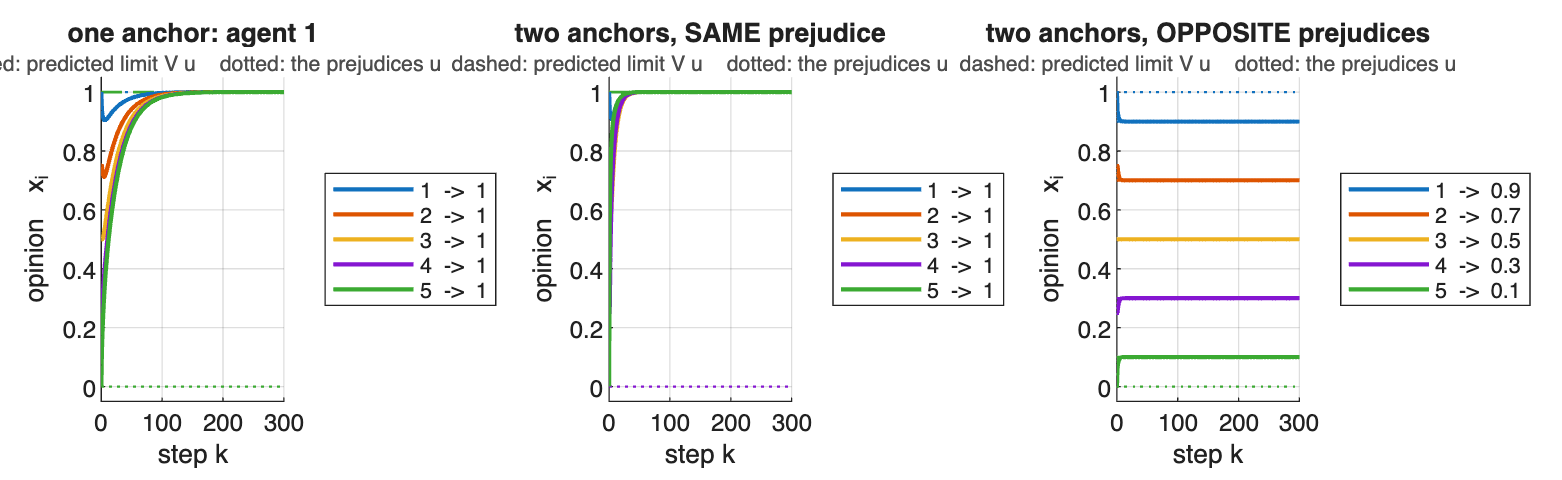

cases = {'one anchor: agent 1',              [0.5; 1; 1; 1; 1  ], [1; 0; 0; 0; 0]; ...
         'two anchors, SAME prejudice',      [0.5; 1; 1; 1; 0.5], [1; 0; 0; 0; 1]; ...
         'two anchors, OPPOSITE prejudices', [0.5; 1; 1; 1; 0.5], [1; 0; 0; 0; 0]};

figure('Position',[0 0 1300 400]);
tiledlayout(1, 3, 'TileSpacing','compact', 'Padding','compact');
for c = 1:3
    lamc = cases{c,2};  uc = cases{c,3};
    X = sim_friedkin_johnsen(W, lamc, uc, x0, 300);
    nexttile;
    plot_opinions(X, [], 'Limit', fj_equilibrium(W, lamc, uc), 'Prejudice', uc, ...
        'Title', cases{c,1}, 'Subtitle','dashed: predicted limit V u    dotted: the prejudices u');
    ylim([-0.05 1.05]);
end


for c = 1:3
    lamc = cases{c,2};  uc = cases{c,3};
    r  = fj_report(W, lamc);
    xi = fj_equilibrium(W, lamc, uc);
    fprintf('%-34s stable %d  rank(V) %d  spread %.4f   x(inf) = %s\n', ...
        cases{c,1}, r.stable, rank(total_influence(W, lamc)), max(xi)-min(xi), mat2str(round(xi.',4)));
end

one anchor: agent 1                stable 1  rank(V) 1  spread 0.0000   x(inf) = [1 1 1 1 1]
two anchors, SAME prejudice        stable 1  rank(V) 2  spread 0.0000   x(inf) = [1 1 1 1 1]
two anchors, OPPOSITE prejudices   stable 1  rank(V) 2  spread 0.8000   x(inf) = [0.9 0.7 0.5 0.3 0.1]


INTERPRETATION. The first panel is the one worth dwelling on. A single anchored agent does NOT produce disagreement - the whole group converges to u_1 = 1. What it changes is WHICH consensus is reached: DeGroot would have given the weighted average of everybodys initial opinions, whereas here the group ends on agent 1s prejudice and the initial opinions are erased entirely. The reason is visible in V: with one prejudiced agent, (I - Lambda) has a single non-zero row, so V has a single non-zero column, and being row-stochastic it must equal the matrix of all ones times e_1. One anchor, propagating through a strongly connected network, captures everybody.

The second panel is the guard against the obvious wrong conclusion. There are two anchors here, and the result is still consensus - because both anchors hold the SAME prejudice. So it is not the NUMBER of prejudiced agents that produces disagreement.

The third panel is what does: two anchors pulling in opposite directions. Agent 1 is anchored at 1 and agent 5 at 0, and the final opinions are 0.9, 0.7, 0.5, 0.3, 0.1 - a clean gradient along the line, each agent sitting at a convex combination of the two prejudices weighted by how close it is to each. Persistent disagreement needs at least two anchors that actually DISAGREE.

## 6. Experiment 4 - a prejudice only controls the agents it can reach

QUESTION. Experiment 3 relied on the graph being strongly connected, so that one prejudice could reach everybody. What happens when it cannot? This is the one place where the structural theory of Part I is needed.

WHY A DIFFERENT NETWORK. Experiments 1-3 all rely on strong connectivity. This one exists to show what happens when a prejudice CANNOT reach some agents, and on a strongly connected graph that is impossible by definition: Corollary 4.1 says strong connectivity plus Lambda different from I makes every agent P-dependent. So changing network here is not a matter of taste - this experiment is precisely the violation of the hypothesis the other three relied on. That is also the cleanest way to read it: Experiments 1-3 show what happens INSIDE the hypothesis, and this one shows what the hypothesis was buying.

SETUP. Four agents. Agent 1 is prejudiced (lambda_1 = 0.5, u_1 = 1); agents 3 and 4 form a closed pair that listens only to itself. The two networks differ by a SINGLE edge: in B, agent 3 also listens to agent 2. Part I splits the agents into P-dependent ones, which some prejudice reaches through a walk in the graph, and P-independent (oblivious) ones, which none does.

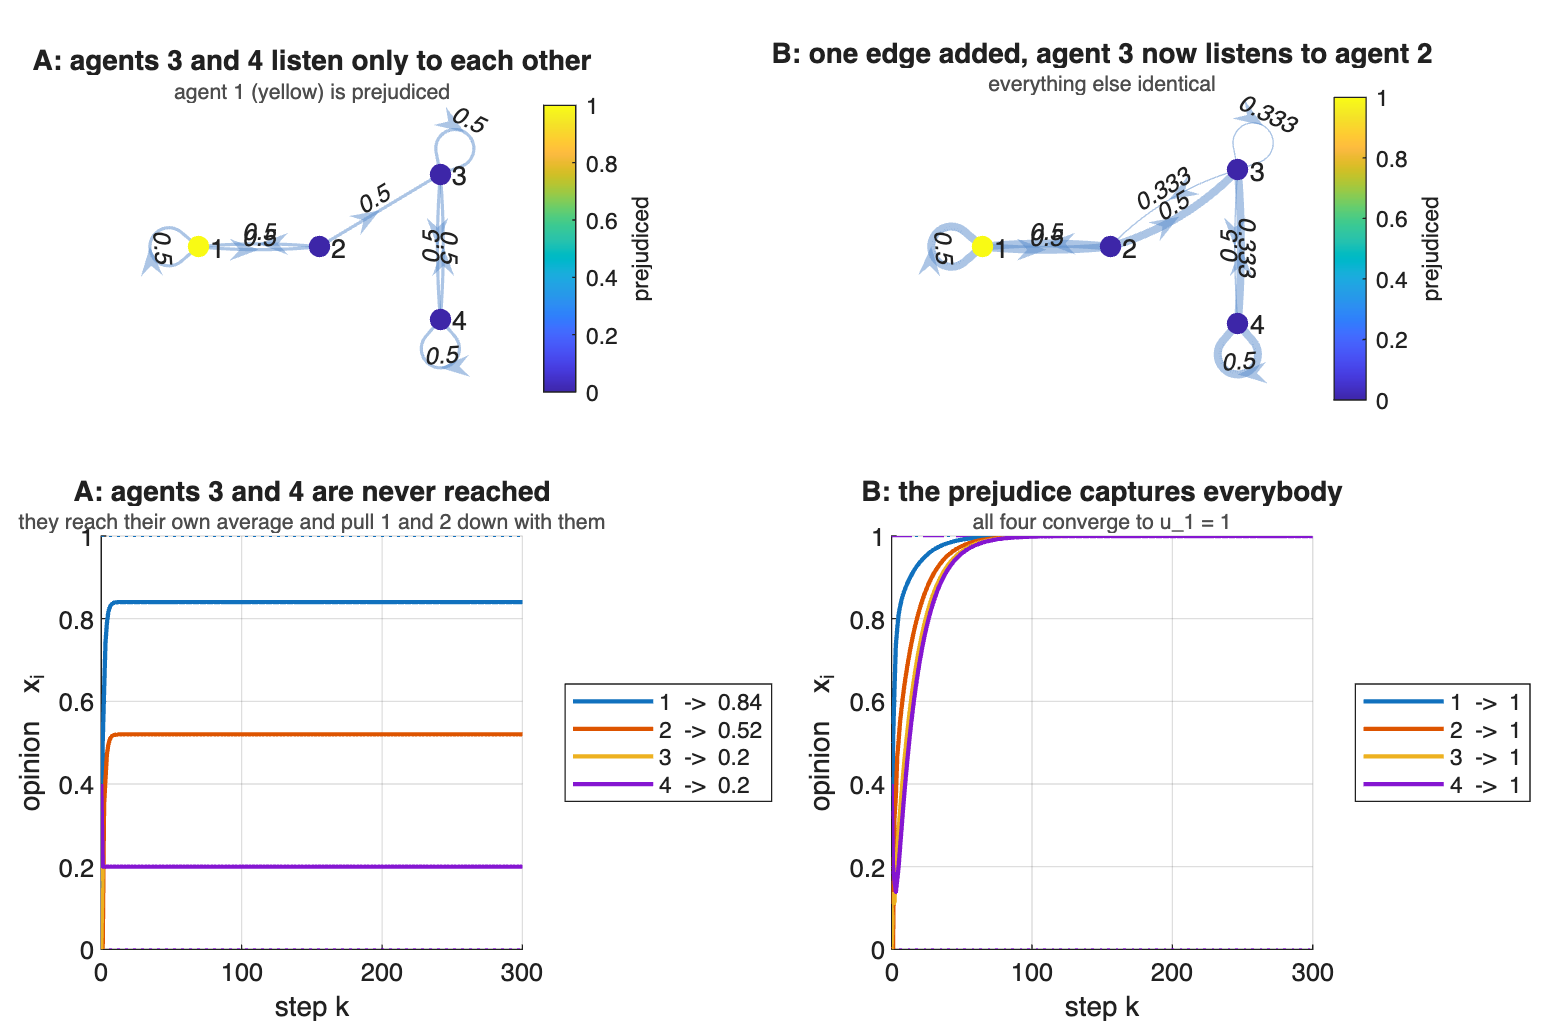

Wa = zeros(4);
Wa(1,[1 2]) = 1;      % 1 listens to itself and 2
Wa(2,[1 3]) = 1;      % 2 listens to 1 and 3
Wa(3,[3 4]) = 1;      % 3 listens to itself and 4     <- closed pair
Wa(4,[3 4]) = 1;      % 4 listens to 3 and itself     <- closed pair
Wa = row_stochastic(Wa);

Wb = Wa;  Wb(3,:) = 0;  Wb(3,[2 3 4]) = 1;            % the single added edge: 3 listens to 2
Wb = row_stochastic(Wb);

lamT = [0.5; 1; 1; 1];        % only agent 1 is prejudiced
uT   = [  1; 0; 0; 0];        % and its prejudice is 1
x0T  = [  0; 0; 0; 0.4];      % the closed pair starts far from agent 1's prejudice

posT = [0 0; 1 0; 2 0.6; 2 -0.6];
figure('Position',[0 0 1150 760]);
tiledlayout(2, 2, 'TileSpacing','compact', 'Padding','compact');

nexttile;
plot_graph(Wa, [], 'Layout', posT, 'NodeValue', double(lamT < 1), 'NodeName','prejudiced', ...
    'Title','A: agents 3 and 4 listen only to each other', 'Subtitle','agent 1 (yellow) is prejudiced');
nexttile;
plot_graph(Wb, [], 'Layout', posT, 'NodeValue', double(lamT < 1), 'NodeName','prejudiced', ...
    'Title','B: one edge added, agent 3 now listens to agent 2', 'Subtitle','everything else identical');

nexttile;
Xa = sim_friedkin_johnsen(Wa, lamT, uT, x0T, 300);
plot_opinions(Xa, [], 'Prejudice', uT, 'Title','A: agents 3 and 4 are never reached', ...
    'Subtitle','they reach their own average and pull 1 and 2 down with them');
nexttile;
Xb = sim_friedkin_johnsen(Wb, lamT, uT, x0T, 300);
plot_opinions(Xb, [], 'Limit', fj_equilibrium(Wb, lamT, uT), 'Prejudice', uT, ...
    'Title','B: the prejudice captures everybody', 'Subtitle','all four converge to u_1 = 1');

fprintf('--- network A\n');  fj_report(Wa, lamT);

--- network A
prejudiced (lambda < 1) : 1
frozen     (lambda = 0) : (none)
P-dependent             : [1 2]   (2 of 4)
P-independent           : [3 4]
rho(Lambda W)           : 1.000000
rho(Lambda11 W11)       : 0.500000   < 1 always, by Theorem 4.1
W22 regular             : 1
asymptotically stable   : 0   (Corollary 4.1: all agents P-dependent)
convergent              : 1   (Corollary 4.2)
  -> x(inf) = V u does NOT apply; the limit depends on x(0).


fprintf('\n--- network B\n');  fj_report(Wb, lamT);


--- network B
prejudiced (lambda < 1) : 1
frozen     (lambda = 0) : (none)
P-dependent             : [1 2 3 4]   (4 of 4)
P-independent           : (none)
rho(Lambda W)           : 0.936313
rho(Lambda11 W11)       : 0.936313   < 1 always, by Theorem 4.1
asymptotically stable   : 1   (Corollary 4.1: all agents P-dependent)
convergent              : 1   (Corollary 4.2)



fprintf('\nDoes the limit depend on the initial opinions?\n');


Does the limit depend on the initial opinions?


for x = {[0;0;0;0.4], [0;0;0.8;0]}
    La = sim_friedkin_johnsen(Wa, lamT, uT, x{1}, 800);
    Lb = sim_friedkin_johnsen(Wb, lamT, uT, x{1}, 800);
    fprintf('  x(0) = %-12s   A -> %-26s   B -> %s\n', mat2str(x{1}.'), ...
        mat2str(round(La(:,end).',4)), mat2str(round(Lb(:,end).',4)));
end

  x(0) = [0 0 0 0.4]    A -> [0.84 0.52 0.2 0.2]          B -> [1 1 1 1]
  x(0) = [0 0 0.8 0]    A -> [0.88 0.64 0.4 0.4]          B -> [1 1 1 1]


Three details of the design are deliberate. Four agents is the smallest size that holds the three roles the example needs: an agent with a prejudice, an agent the prejudice reaches, and a group it does not. The unreached group is a PAIR rather than a single agent, because a lone closed agent would be visually indistinguishable from a frozen one with lambda = 0, whereas a pair runs a non-trivial French-DeGroot model of its own - here averaging 0 and 0.4 down to 0.2. That is the real point: oblivious agents are not frozen, they have their own autonomous dynamics that the prejudice has no access to, which is exactly what it means for the block W22 to be itself a stochastic matrix. Finally, the two networks differ by exactly ONE edge, so the whole difference in outcome is attributable to it and the abstract condition "P-dependent" becomes a single structural bit - and note that the DIRECTION of that edge is the entire content, since W(3,2) > 0 means agent 3 listens to agent 2, which is what makes 3 P-dependent, while the reverse edge would not.

INTERPRETATION. In network A the prejudice of agent 1 cannot reach agents 3 and 4: there is no walk from either of them to agent 1, so nothing agent 1 believes ever enters their update. They are P-independent, they run an ordinary DeGroot model among themselves, and they settle on their own average, 0.2, completely unmoved by anything agent 1 believes. They then drag agent 2 down to 0.52, and through it agent 1 to 0.84, below its own prejudice of 1. Adding the single edge in B makes all four agents P-dependent and the prejudice captures the whole network.

The report makes the mechanism explicit and matches Part I exactly. In A, rho(Lambda W) = 1, so the model is NOT asymptotically stable and the formula x(inf) = V u does not apply - and indeed the printed table shows As limit moving when x(0) moves, while Bs does not. But notice that rho(Lambda11 W11) = 0.5, comfortably below 1: the P-dependent block is asymptotically stable on its own, exactly as Theorem 4.1 guarantees, whatever the rest of the network does. All the instability lives in the oblivious block.

The practical statement, and the one worth keeping: asymptotic stability of the FJ model holds if and only if EVERY agent is P-dependent (Corollary 4.1). This is the mirror image of the consensus condition in DeGroot - for consensus you need one agent that reaches everybody, for stability you need the set of anchors to reach everybody.

## 7. What this notebook shows

- Stubbornness adds one term. FJ is DeGroot plus a constant pull towards a pre-existing opinion that is re-applied at every step and never decays; lambda_i = 1 recovers DeGroot exactly, lambda_i = 0 freezes the agent on its prejudice.

- That term is what makes persistent disagreement possible. In DeGroot every update is a convex combination, so the spread can only shrink to zero on a connected aperiodic graph. In FJ the group converges to a stable configuration in which the agents still disagree, on a network that is fully connected and in which everybody keeps listening (Experiment 1).

- The susceptibility is a genuine trade-off, not a free parameter. rho(Lambda W) = lambda for a uniform Lambda: raising lambda shrinks the final disagreement but slows convergence, and at lambda = 1 the disagreement vanishes together with the asymptotic stability (Experiment 2).

- What produces disagreement is disagreement among the ANCHORS, not their number. One prejudiced agent in a strongly connected network still gives consensus - at its own prejudice, with the initial opinions erased - and so do two agents holding the same prejudice. Two conflicting prejudices give a gradient of opinions across the network (Experiment 3).

- A prejudice only controls the agents it can reach. The FJ model is asymptotically stable if and only if every agent is P-dependent; where oblivious agents exist, rho(Lambda W) = 1, the limit depends on x(0) again, and the oblivious block drags the rest - though the P-dependent block remains stable on its own, by Theorem 4.1 (Experiment 4).

- Compared with DeGroot the structural change is the rank of the limit operator: DeGroots is 1 p, of rank one, so only agreement is reachable; FJs is V = (I - Lambda W)^-1 (I - Lambda), generically of full rank and always row-stochastic - so the disagreement is persistent but bounded, always inside the convex hull of the prejudices.